clc
clear
RGB = readmatrix('thickness_all\thickness2rgb.csv');
t = RGB(:,1);
rgb_v = RGB(:,2:4)/256;
xyz_v = rgb2xyz(rgb_v);

x = 1000;       %薄膜厚度/nm
n = 1.428;      %薄膜折射率
n0 = 1;         %空气折射率
ng = 3.836;     %硅片折射率
i = 0;          %折射角
lambda = 360:830;
x = 1:x;
delta = 4*pi*n*x'*cos(i)./lambda;
R = (n^2*(n0-ng)^2*cos(delta/2).^2+(n^2-n0*ng)^2*sin(delta/2).^2)./...
       (n^2*(n0+ng)^2*cos(delta/2).^2+(n^2+n0*ng)^2*sin(delta/2).^2);
cie = colorMatchFcn('1931_full');
XYZ = R*cie(:,2:4);
xyz_norm = normalize(XYZ,2,'norm',1);
rgb = xyz2rgb(xyz_norm);

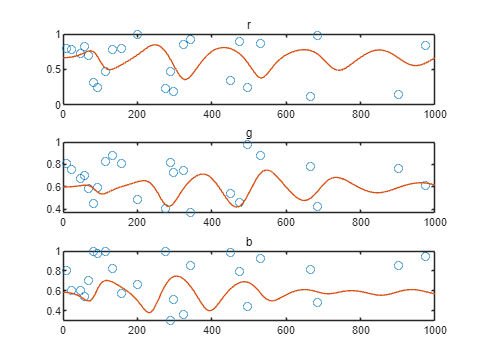

subplot(3,1,1)
plot(t,rgb_v(:,1),'o')
title('r')
hold on
plot(rgb(:,1))
hold off
subplot(3,1,2)
plot(t,rgb_v(:,2),'o')
title('g')
hold on
plot(rgb(:,2))
hold off
subplot(3,1,3)
plot(t,rgb_v(:,3),'o')
title('b')
hold on
plot(rgb(:,3))
hold off

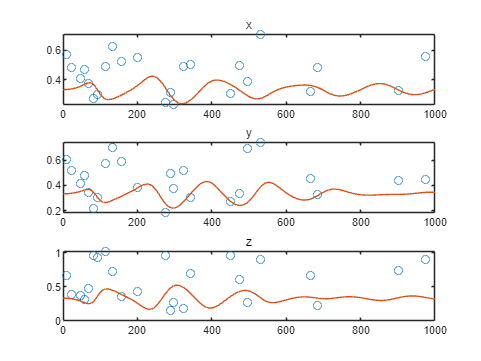

subplot(3,1,1)
plot(t,xyz_v(:,1),'o')
title('x')
hold on
plot(xyz_norm(:,1))
hold off
subplot(3,1,2)
plot(t,xyz_v(:,2),'o')
title('y')
hold on
plot(xyz_norm(:,2))
hold off
subplot(3,1,3)
plot(t,xyz_v(:,3),'o')
title('z')
hold on
plot(xyz_norm(:,3))
hold off

f = @(x)res(x, cie, R, t, xyz_v);
x0 = [0.01 0.01 0.01];   %初始值
options = optimoptions(@fmincon,'Algorithm','sqp','MaxIterations',1000);
[x,fval] = fmincon(f,x0,[],[],[],[],[0 0 0],[1 1 1],[],options)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.0202         0         0


fval = 4.6963

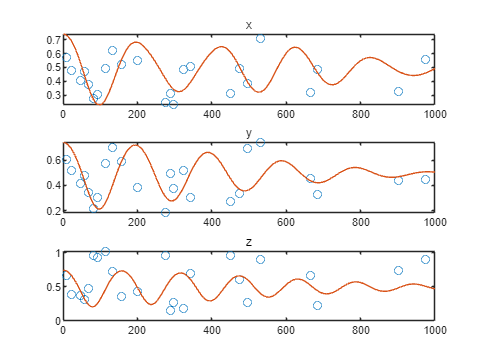

xyz_t = model(x, cie, R);
subplot(3,1,1)
plot(t,xyz_v(:,1),'o')
title('x')
hold on
plot(xyz_t(:,1))
hold off
subplot(3,1,2)
plot(t,xyz_v(:,2),'o')
title('y')
hold on
plot(xyz_t(:,2))
hold off
subplot(3,1,3)
plot(t,xyz_v(:,3),'o')
title('z')
hold on
plot(xyz_t(:,3))
hold off

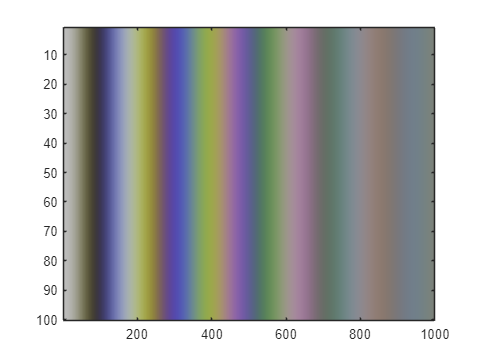

r = xyz_t(:,1)';
g = xyz_t(:,2)';
b = xyz_t(:,3)';
C(:,:,1) = r.*ones(100,1);
C(:,:,2) = g.*ones(100,1);
C(:,:,3) = b.*ones(100,1);
figure
image(C)

function r = res(x, cie, R, t, xyz_v)
    X_t = R.*(x(1)+x(2)*cie(:,2)+x(3)*cie(:,2).^2)'*cie(:,2);
    Y_t = R.*(x(1)+x(2)*cie(:,3)+x(3)*cie(:,3).^2)'*cie(:,3);
    Z_t = R.*(x(1)+x(2)*cie(:,4)+x(3)*cie(:,4).^2)'*cie(:,4);
    xyz_t = [X_t, Y_t, Z_t];
    diff = (xyz_t(t)-xyz_v).^2;
    r = sum(diff,"all");
end
function xyz = model(x, cie, R)
    X_t = R.*(x(1)+x(2)*cie(:,2)+x(3)*cie(:,2).^2)'*cie(:,2);
    Y_t = R.*(x(1)+x(2)*cie(:,3)+x(3)*cie(:,3).^2)'*cie(:,3);
    Z_t = R.*(x(1)+x(2)*cie(:,4)+x(3)*cie(:,4).^2)'*cie(:,4);
    xyz = [X_t, Y_t, Z_t];
end